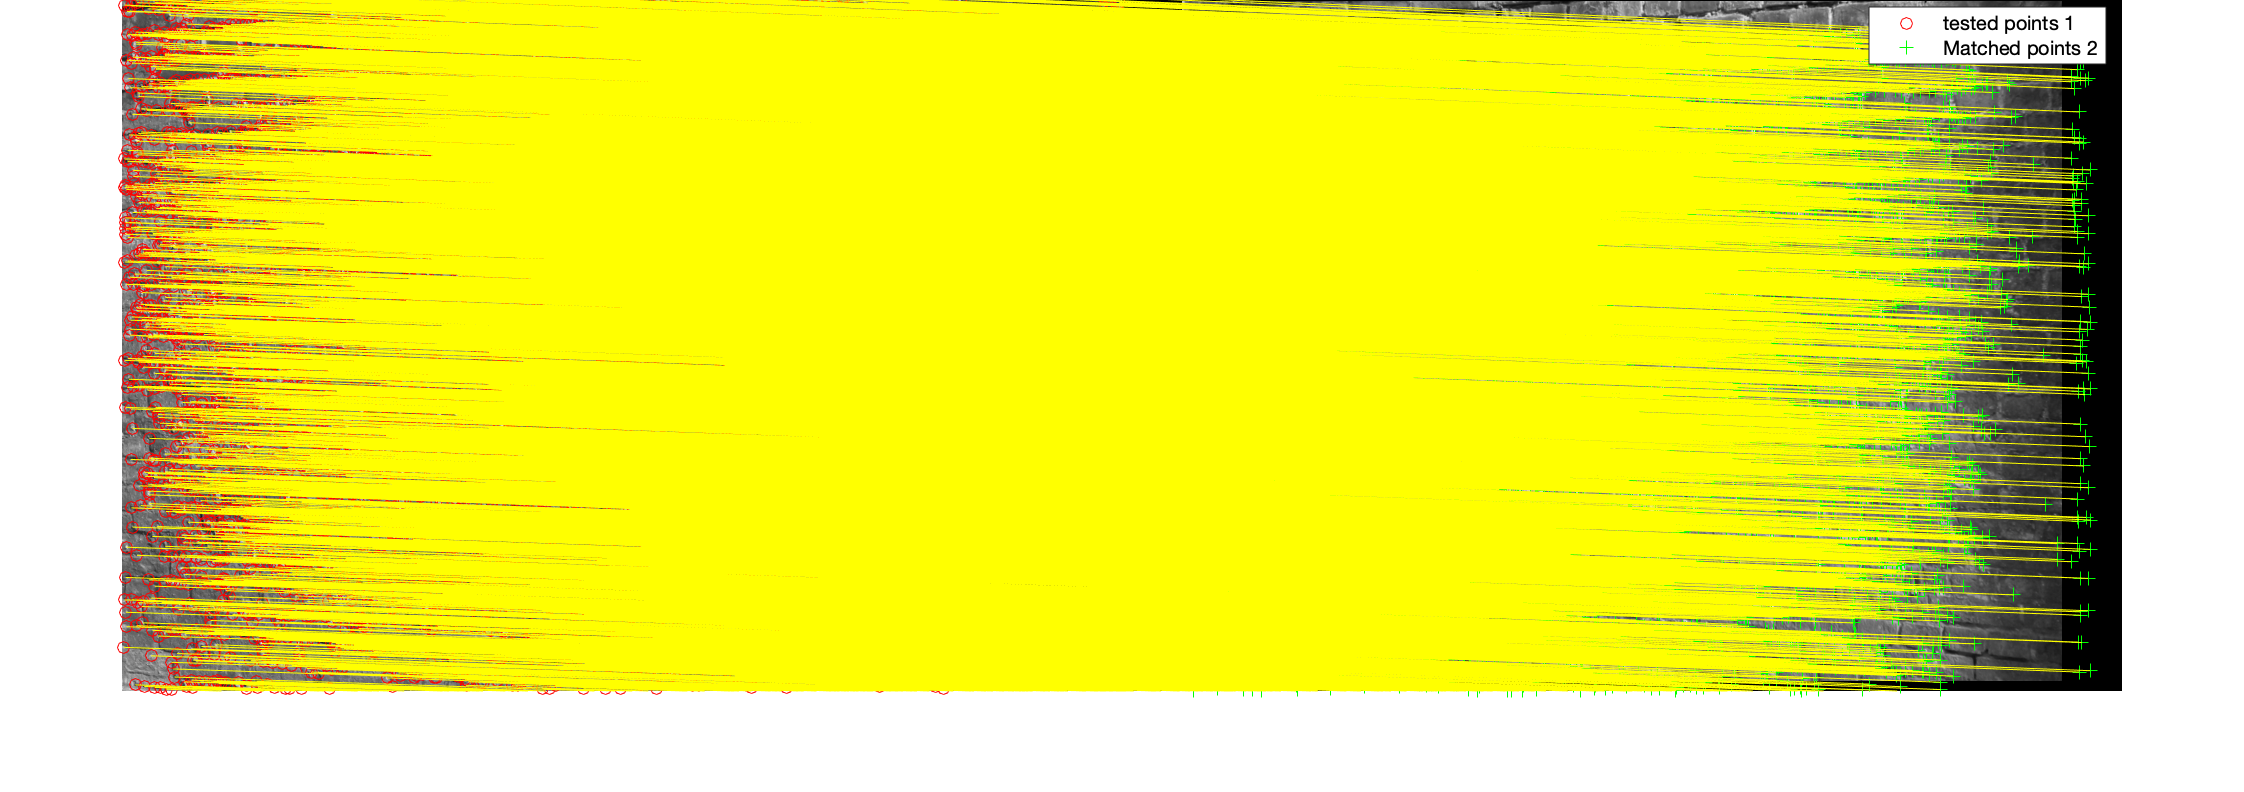

pos2 = 7220×2 single 矩阵
  -13.0655  681.5656
  -13.9616   43.6889
  -13.7012  196.4592
  -13.2893  224.8435
  -12.8201  396.5249
  -12.4934  634.4434
  -12.8081  223.2336
  -12.8209  254.9962
  -12.8666  259.7573
  -12.1536  265.8431


clear 

I1=imread("training_images/wall/img1.png");
I2=imread("training_images/wall/img2.png");

I1=im2double(I1);
I2=im2double(I2);


detector=detectHarrisFeatures(rgb2gray(I1));
pos1=detector.Location;


[pos2]=find_matches(I1,pos1,I2)